# **Term-Premium Modelling using the ACM Model**

After a long regime of near-zero base interest rates, the return of base interest rates in developed economies to more realistic historical levels has inspired a greater interest in term-premium modelling methodologies.

The *term premium* is the additional compensation, or premium, associated with an investment in a long-term bond compared with rolling over a sequence of short-term bonds. For example, when investing for a period of 10 years, an investor could purchase a 10-year bond, or purchase a sequence of ten 1-year bonds. The term premium compensates long-term bond investors for the additional interest rate risk they incur. The interest rate risk takes the following form: if an investor is tied into a long-term bond and the base interest rate rises, then they miss out on the higher returns available on short-term bonds. No credit risk is assumed in these models, as they are generally used for government-issued securities.

During a near-zero interest rate regime, such as the period from the global financial crisis (2007-2008) to the end of 2021, long-term bonds are more attractive due to their higher return. As interest rates increase, short-term bonds become more competitive and long-term bonds lose some of their appeal. The dynamics of the term premium provide central bankers and investors with more quantitative insight into these market processes.

This script demonstrates how to fit the Adrian-Crump-Moench (ACM) term-premium model to a set of yield curves, based on the ACM 2013 paper.

- [Pricing the Term Structure with Linear Regressions](https://www.newyorkfed.org/medialibrary/media/research/staff_reports/sr340.pdf), Tobias Adrian, Richard K. Crump, and Emanuel Moench, Federal Reserve Bank of New York Staff Reports, no. 340, August 2008; revised April 2013, JEL classification: G10, G12.

For further references and background information, please see the References section below.

## Download the data used in the ACM 2013 paper.

filename = "feds200628.xls";

try
    if ~isfile( filename )
        websave( filename, "https://www.federalreserve.gov/econresdata/researchdata/feds200628.xls" );
    end % if
catch 
    error( "TermPremiumModelling:DownloadAndSaveFailed", ...
        "Unable to download and/or save data. Check your internet " + ...
        "connection and file access permissions." )
end % try/catch

## Import the ACM 2013 data as a timetable.

svenData = readtable( filename );
svenData.(1) = datetime( svenData.(1) );
svenData = table2timetable( svenData );
svenData.Properties.DimensionNames(1) = "Date";
svenData = sortrows( svenData );
disp( head( svenData ) )

       Date        SVENY01    SVENY02    SVENY03    SVENY04    SVENY05    SVENY06    SVENY07    SVENY08    SVENY09    SVENY10    SVENY11    SVENY12    SVENY13    SVENY14    SVENY15    SVENY16    SVENY17    SVENY18    SVENY19    SVENY20    SVENY21    SVENY22    SVENY23    SVENY24    SVENY25    SVENY26    SVENY27    SVENY28    SVENY29    SVENY30    SVENPY01    SVENPY02    SVENPY03    SVENPY04    

## Extract the Svensson model parameters and dates matching the range used in ACM 2013.

Extrapolate where needed so that we have one data point for each month.

tr = timerange( datetime( 1987, 1, 1 ), datetime( 2011, 12, 31 ) );
svenData = svenData( tr, ["SVENY02", "BETA0", "BETA1", "BETA2", "BETA3", "TAU1", "TAU2"] );
svenData = retime( svenData, "monthly", "nearest" );
svenData(end, :) = [];
disp( head( svenData ) )

       Date        SVENY02    BETA0      BETA1      BETA2     BETA3      TAU1       TAU2  
    ___________    _______    ______    _______    _______    ______    _______    _______

    01-Jan-1987    6.3105     8.8124    -3.2289    -620.33    618.06     2.0111     2.0066
    01-Feb-1987    6.2804      8.694    -2.9329    -620.37    618.01     2.0756      2.073
    01-Mar-1987    6.2788     8.4822    -2.8846     -620.2    618.19     1.9104     1.9065
    01-Apr-1987    6.6066     8.7423    -2.8986    -620.06    618.33     1.8327     1.8295
    01-May-1987    7.3905     8.9959    -3.8751    -619.14    619.26    0.84575    0.84261
    <

## Construct a collection of yield curves using the Svensson model.

Extract the Svensson parameters.

Beta0 = svenData.BETA0;
Beta1 = svenData.BETA1;
Beta2 = svenData.BETA2;
Beta3 = svenData.BETA3;
Tau1 = svenData.TAU1;
Tau2 = svenData.TAU2;

Define the required bond maturities, expressed in years from one month to ten years.

monthlyMaturities = 1:120;
annualMaturities = monthlyMaturities / 12;

Compute yields using the Svensson model.

numObs = height( svenData );
yields = zeros( numObs, numel( annualMaturities ) ); % VECTORISE
for t = 1 : numObs
    s = Beta0(t) + ...
    Beta1(t) * (1 - exp( -annualMaturities / Tau1(t) )) .* (Tau1(t) ./ annualMaturities) + ...
    Beta2(t) * ((1 - exp( -annualMaturities / Tau1(t) )) .* Tau1(t) ./ annualMaturities - exp( -annualMaturities ./ Tau1(t) )) + ...
    Beta3(t) * ((1 - exp( -annualMaturities / Tau2(t) )) .* (Tau2(t) ./ annualMaturities) - exp( -annualMaturities / Tau2(t) ));
    yields(t, :) = s;
end % for

yields = array2timetable( yields, "RowTimes", svenData.Date, ...
    "VariableNames", string( monthlyMaturities ) );
yields.Properties.DimensionNames(1) = svenData.Properties.DimensionNames(1);

Write down an estimate for the short-term interest rate using the first yield curve.

stir = array2timetable( yields{:, 1}, ...
    "RowTimes", yields.Date, ...
    "VariableNames", "ShortTermRate" );

Write down the number of maturities.

numMaturities = width( yields );

## Visualize the yield curves.

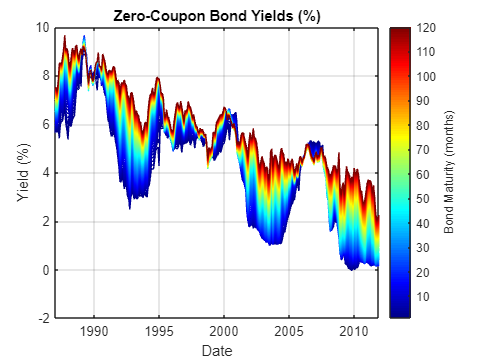

figure
ax = axes();
plot( ax, yields.Date, yields.Variables )
xlabel( ax, "Date" )
ylabel( ax, "Yield (%)" )
title( ax, "Zero-Coupon Bond Yields (%)" )
grid( ax, "on" )
ax.ColorOrder = jet( numMaturities );
colormap( ax, jet( numMaturities ) )
ax.CLim = [1, numMaturities];
c = colorbar( ax );
ylabel( c, "Bond Maturity (months)" )

## Specify the model options.

Number of principal components to use.

numComponents = 5;

Specify the maturity options, in months.

maturities = 1:120;

The maturities to use for computing the principal components of the yield matrix.

maturitiesPCA = 3:120; 

The maturities to use for computing the excess returns.

maturitiesRX = [6:6:60, 84, 120];

## Fit the model.

See [`fitACM`](matlab: edit fitACM) and [`pdynamics`](matlab: edit pdynamics) for details.

decomposition = fitACM( yields, stir, maturities, ...
    "NumComponents", numComponents, ...
    "FactorMaturities", maturitiesPCA, ...
    "ExcessReturnMaturities", maturitiesRX );

## Plot the 2-year and 10-year decompositions.

See `plotDecomposition`.

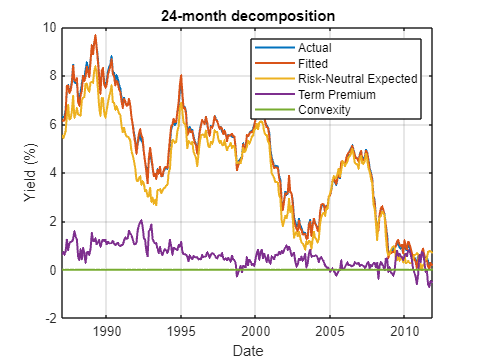

figure
ax = axes();
plotDecomposition( ax, yields, decomposition, 24 )

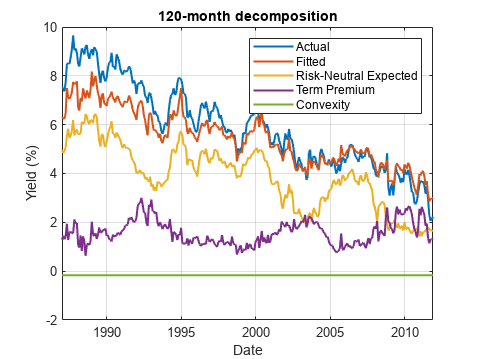

figure
ax = axes();
plotDecomposition( ax, yields, decomposition, 120 )

## References

- [Pricing the Term Structure with Linear Regressions](https://www.newyorkfed.org/medialibrary/media/research/staff_reports/sr340.pdf), Tobias Adrian, Richard K. Crump, and Emanuel Moench, Federal Reserve Bank of New York Staff Reports, no. 340, August 2008; revised April 2013, JEL classification: G10, G12

- [Bank of England Working Paper No. 518: Evaluating the robustness of UK term structure decompositions using linear regression methods](https://www.bankofengland.co.uk/-/media/boe/files/working-paper/2014/evaluating-the-robustness-of-uk-term-structure-decompositions-using-linear-regression-methods.pdf), Sheheryar Malik and Andrew Meldrum

- [Bond Risk Premia](https://web.stanford.edu/~piazzesi/cp.pdf), John H. Cochrane and Monika Piazzesi

- [Term premium dynamics in an emerging market: Risk, liquidity, and behavioral factors](https://www.sciencedirect.com/science/article/abs/pii/S1057521922003052), Cenk C. Karahan, Emre Soykök, International Review of Financial Analysis, Volume 84, November 2022, 102355

- [Term premium in emerging market sovereign yields: Role of common and country specific factors](https://www.sciencedirect.com/science/article/pii/S1303070120300378), Ibrahim Ozbek, Irem Talasl, Central Bank Review, Volume 20, Issue 4, December 2020, Pages 169-182

- [The U.S. Treasury yield curve: 1961 to the present](https://www.sciencedirect.com/science/article/abs/pii/S0304393207000840), Refet S. Gürkaynak, Brian Sack, Jonathan H. Wright, Journal of Monetary Economics, Volume 54, Issue 8, November 2007, Pages 2291-2304

- [Federal Reserve Economic Research Data](https://www.federalreserve.gov/econresdata/researchdata/feds200628.xls), accessed July 2025.

## Local functions.

function plotDecomposition( ax, yields, decomposition, numMonths )

plot( ax, yields.Date, yields{:, numMonths}, "LineWidth", 1.5 )
hold on
plot( ax, decomposition.FittedYields.Date, decomposition.FittedYields{:, numMonths}, "LineWidth", 1.5 )
plot( ax, decomposition.RiskNeutralExpectedValues.Date, decomposition.RiskNeutralExpectedValues{:, numMonths}, "LineWidth", 1.5 )
plot( ax, decomposition.TermPremium.Date, decomposition.TermPremium{:, numMonths}, "LineWidth", 1.5 )
plot( ax, decomposition.Convexity.Date, decomposition.Convexity{:, numMonths}, "LineWidth", 1.5 )
xlabel( ax, "Date" )
ylabel( ax, "Yield (%)" )
title( ax, string( numMonths ) + "-month decomposition" )
grid( ax, "on" )
legend( ax, ["Actual", "Fitted", "Risk-Neutral Expected", "Term Premium", "Convexity"] )

end % plotDecomposition